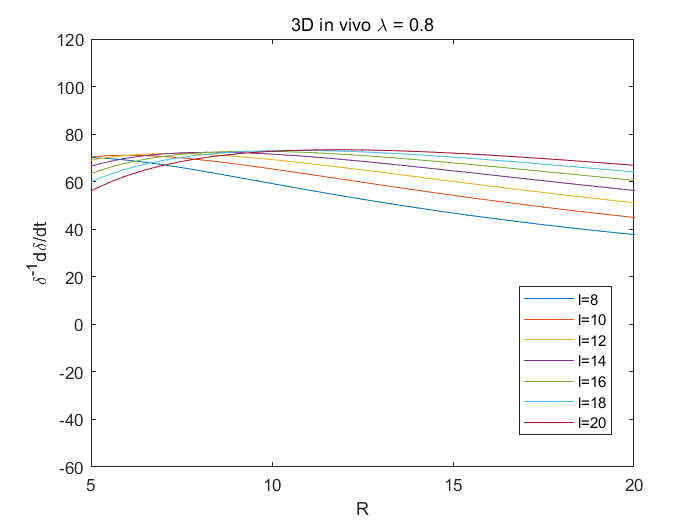

clc;clear;close;

% m effects on sign of evo fcn is not that obvious compared to l

% m1=0;% threshold for l=3: 0.01-0.02; 
% thres for l=8: 0.04-0.05; thres for l=12: 0.05 and 0.1;
% thres for l=16: 0.08-0.1
%thres for l=20: 0.1-0.2
G=1;
C_b=10;

m1 = 20;
R = 0:0.1:50;
%R = 5:0.1:20;

%m1=200; % threshold for l=3: smaller than lambda=0.01; 
% thres for l=8: in 0.01 and 0.02; thres for l=12: 0.02 and 0.03;
% thres for l=16: 0.04-0.05
%thres for l=20: 0.05-0.1

xmin = 5; % X轴的最小值
xmax = 20; % X轴的最大值
%xlim([xmin xmax])
ymin = -60; % X轴的最小值
ymax = 120; % X轴的最大值
%ylim([ymin ymax])

% lambda=0.8;
lambda=0.8;
l = [8 10 12 14 16 18 20];

for i=1:length(l)
    sigma2= v_3D(l(i),R,m1,lambda,C_b,G);
    plot(R, sigma2)
    axis([xmin xmax ymin ymax])
    hold on
end
title('3D in vivo \lambda = 0.8')
legend('l=8','l=10','l=12','l=14','l=16','l=18','l=20')
legend('location','best')
xlabel('R')
ylabel('\delta^{-1}d\delta/dt')
%plot(R,sigma);
hold off;

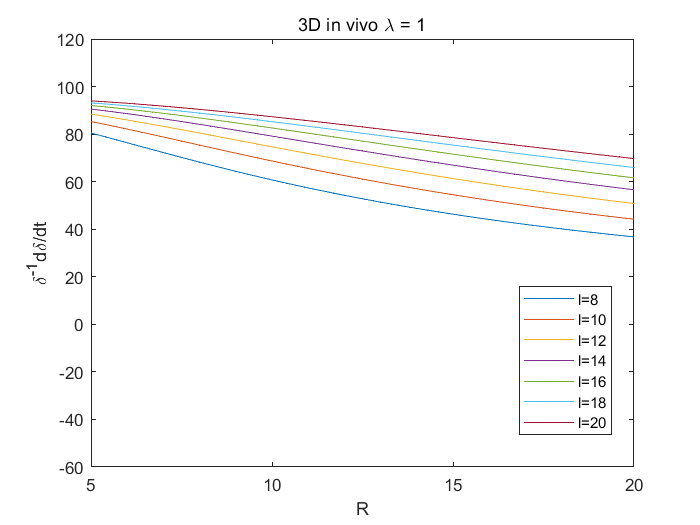



% lambda = 1;
lambda=1;
G=1;
C_b=10;
l = [8 10 12 14 16 18 20];

for i=1:length(l)
    sigma2= v_3D(l(i),R,m1,lambda,C_b,G);
    plot(R, sigma2)
    axis([xmin xmax ymin ymax])    
    hold on
end
title('3D in vivo \lambda = 1')
legend('l=8','l=10','l=12','l=14','l=16','l=18','l=20')
legend('location','best')
xlabel('R')
ylabel('\delta^{-1}d\delta/dt')
%plot(R,sigma);
hold off;

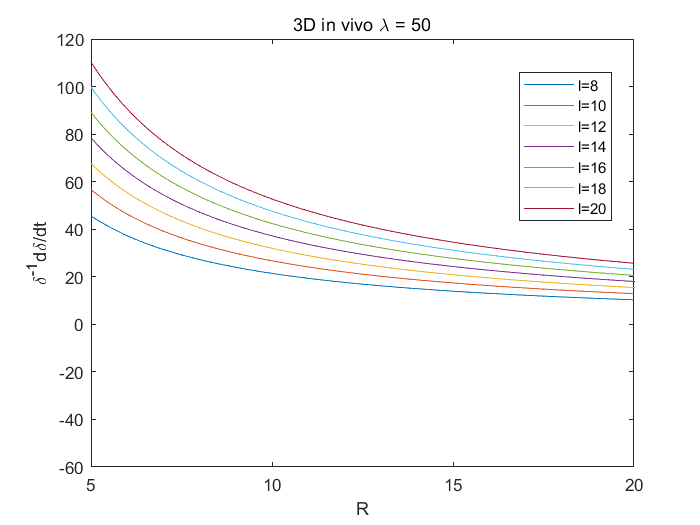


% lambda = 50;
lambda=50;
G=1;
C_b=10;
l = [8 10 12 14 16 18 20];

for i=1:length(l)
    sigma2= v_3D(l(i),R,m1,lambda,C_b,G);
    plot(R, sigma2)
    axis([xmin xmax ymin ymax])    
    hold on
end
title('3D in vivo \lambda = 50')
legend('l=8','l=10','l=12','l=14','l=16','l=18','l=20')
legend('location','best')
xlabel('R')
ylabel('\delta^{-1}d\delta/dt')
%plot(R,sigma);
hold off;

function sigma= v_3D(l,R,m,lambda,C_b,G)
    %%sigma_A = (G.*C_b.*((( (l+m.*l+1).*((3.*R+2).*lambda.^(3/2)+sqrt(lambda).*(R-2) ).*R.*besselk(l+1/2, R) +2.* besselk(l-1/2, R).*(R+1).*(R.*(R-m.*l./2-1).*lambda.^(3/2)-(m.*l+2).*(R-2).*sqrt(lambda)./2 + m.*l.*lambda.*(-2+(lambda+1).*R)./2)) .*cosh( (sqrt(lambda).*R).^3 ) + sinh(sqrt(lambda).*R).* ((l+m*l+1).*((lambda.^2+3.*lambda).*R+lambda.^2-1).*R .*besselk(l+1/2, R)+besselk(l-1/2, R).*(R+1).*((2.*R.*m.*l-m.*l).*lambda.^(3/2)-m.*l.*sqrt(lambda)+(lambda.^2+lambda).*R.^2-2*lambda.*(m.*l+2).*R+(lambda+1).*(m.*l+2))).*cosh( (sqrt(lambda).*R).^2 )+(-((2.*R+2).*lambda.^(3/2)+sqrt(lambda).*(R-2)).*(l+m.*l+1).*R.* besselk(l+1/2, R) -2.*(lambda.^(3/2).*R.^2+(R-2).*((-m*l-2).*sqrt(lambda)+m*l*lambda)./2 ).* besselk(l-1/2, R).*(R+1)).*cosh(sqrt(lambda).*R)-sinh(sqrt(lambda).*R).*(R.*(l+m*l+1).*(lambda.*R+lambda-1).*besselk(l+1/2, R)+besselk(l-1/2, R).*(R+1).*(R.^2.*lambda-m*l*sqrt(lambda)+m*l+2))).*besseli(l+1/2, sqrt(lambda).*R)+besselk(l+1/2, R).*((m*l.*(R+1).*(R-2).*lambda.^(3/2)+R.*m*l.*(R+1).*lambda.^(5/2)-lambda.*(-2+(lambda+1).*R).*(R.^2+ (m*l+2).*R+m*l+2)).*cosh( (sqrt(lambda).*R).^3 )-2.*((R-1/2).*(R.^2+(m*l+2).*R+m*l+2).*lambda.^(3/2)+(-R.^2/2+(-m*l/2-1).*R-m*l/2-1).*sqrt(lambda)-m*l.*(R+1).*lambda.*(lambda.*R-lambda./2-1/2)).*sinh(sqrt(lambda).*R).*cosh( (sqrt(lambda).*R).^2 )+(-m.*l.*(R+1).*lambda.^(3/2)+lambda.*(R.^2+(m.*l+2).*R+m*l+2)).*(R-2).*cosh(sqrt(lambda).*R)-sinh(sqrt(lambda).*R).*((R.^2+(m*l+2).*R+m*l+2).*sqrt(lambda)-m*l.*(R+1).*lambda)).*besseli(l-1/2,sqrt(lambda).*R)));
    sigma_A = (G.*C_b.*((( (l+m.*l+1).*((3.*R+2).*lambda.^(3/2)+sqrt(lambda).*(R-2) ).*R.*besselk(l+1/2, R) +2.* besselk(l-1/2, R).*(R+1).*(R.*(R-m.*l./2-1).*lambda.^(3/2)-(m.*l+2).*(R-2).*sqrt(lambda)./2 + m.*l.*lambda.*(-2+(lambda+1).*R)./2)) .*cosh(sqrt(lambda).*R).^3 + sinh(sqrt(lambda).*R).* ((l+m*l+1).*((lambda.^2+3.*lambda).*R+lambda.^2-1).*R .*besselk(l+1/2, R)+besselk(l-1/2, R).*(R+1).*((2.*R.*m.*l-m.*l).*lambda.^(3/2)-m.*l.*sqrt(lambda)+(lambda.^2+lambda).*R.^2-2*lambda.*(m.*l+2).*R+(lambda+1).*(m.*l+2))).*cosh(sqrt(lambda).*R).^2+(-((2.*R+2).*lambda.^(3/2)+sqrt(lambda).*(R-2)).*(l+m.*l+1).*R.* besselk(l+1/2, R) -2.*(lambda.^(3/2).*R.^2+(R-2).*((-m*l-2).*sqrt(lambda)+m*l*lambda)./2 ).* besselk(l-1/2, R).*(R+1)).*cosh(sqrt(lambda).*R)-sinh(sqrt(lambda).*R).*(R.*(l+m*l+1).*(lambda.*R+lambda-1).*besselk(l+1/2, R)+besselk(l-1/2, R).*(R+1).*(R.^2.*lambda-m*l*sqrt(lambda)+m*l+2))).*besseli(l+1/2, sqrt(lambda).*R)+besselk(l+1/2, R).*((m*l.*(R+1).*(R-2).*lambda.^(3/2)+R.*m*l.*(R+1).*lambda.^(5/2)-lambda.*(-2+(lambda+1).*R).*(R.^2+ (m*l+2).*R+m*l+2)).*cosh(sqrt(lambda).*R).^3-2.*((R-1/2).*(R.^2+(m*l+2).*R+m*l+2).*lambda.^(3/2)+(-R.^2/2+(-m*l/2-1).*R-m*l/2-1).*sqrt(lambda)-m*l.*(R+1).*lambda.*(lambda.*R-lambda./2-1/2)).*sinh(sqrt(lambda).*R).*cosh(sqrt(lambda).*R).^2+(-m.*l.*(R+1).*lambda.^(3/2)+lambda.*(R.^2+(m.*l+2).*R+m*l+2)).*(R-2).*cosh(sqrt(lambda).*R)-sinh(sqrt(lambda).*R).*((R.^2+(m*l+2).*R+m*l+2).*sqrt(lambda)-m*l.*(R+1).*lambda)).*besseli(l-1/2,sqrt(lambda).*R)));
    sigma_B =( sqrt(lambda).*( sqrt(lambda).*cosh(sqrt(lambda).*R)+sinh(sqrt(lambda).*R) ).*( besselk(l-1/2, R).*( sqrt(lambda).*cosh(sqrt(lambda).*R) +sinh(sqrt(lambda).*R)).*besseli(l+1/2,sqrt(lambda).*R)+besselk(l+1/2, R).*besseli(l-1/2,sqrt(lambda).*R).*( cosh(sqrt(lambda).*R).*lambda+sinh(sqrt(lambda).*R).*sqrt(lambda) )).*(cosh(sqrt(lambda).*R)*lambda+sinh(sqrt(lambda).*R).*sqrt(lambda)).*R.^3);
    sigma = sigma_A ./ sigma_B;
end